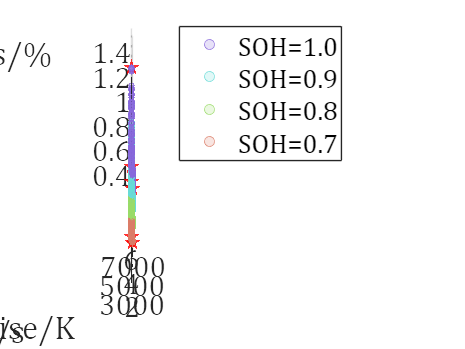

clc;clear;
load("EEI_DATA_100for100_1000_1.mat");
x1 = EEI_DATA.x; y1 = EEI_DATA.y;
y1 = fun1(y1);
load("EEI_DATA_100for90_1000_1.mat");
x2 = EEI_DATA.x; y2 = EEI_DATA.y;
y2 = fun1(y2);
load("EEI_DATA_100for80_1000_1.mat");
x3 = EEI_DATA.x; y3 = EEI_DATA.y;
y3 = fun1(y3);
load("EEI_DATA_100for70_1000_1.mat");
x4 = EEI_DATA.x; y4 = EEI_DATA.y;
y4 = fun1(y4);
% 几个标记出来的点
load("OP1.mat");

% 绘制使用ParEGO得到的不同SOH下的解集
c = ['#8767DB';'#67DBD7';'#99DB67';'#DB7C67';'#AAAC4D';'#DAD986'];
close(figure(1));
figure(1);
scatter3(y1(:,1),y1(:,2),y1(:,3),10,...
    'MarkerFaceColor',c(1,:),'MarkerFaceAlpha',0.2,...
    'MarkerEdgeColor',c(1,:),'MarkerEdgeAlpha',0.8)
hold on;
scatter3(y2(:,1),y2(:,2),y2(:,3),10,...
    'MarkerFaceColor',c(2,:),'MarkerFaceAlpha',0.2,...
    'MarkerEdgeColor',c(2,:),'MarkerEdgeAlpha',0.8)
scatter3(y3(:,1),y3(:,2),y3(:,3),10,...
    'MarkerFaceColor',c(3,:),'MarkerFaceAlpha',0.2,...
    'MarkerEdgeColor',c(3,:),'MarkerEdgeAlpha',0.8)
scatter3(y4(:,1),y4(:,2),y4(:,3),10,...
    'MarkerFaceColor',c(4,:),'MarkerFaceAlpha',0.2,...
    'MarkerEdgeColor',c(4,:),'MarkerEdgeAlpha',0.8)
%%%% 五角星标记 %%%%%
scatter3(OptimalProtocol(:,6),OptimalProtocol(:,7),OptimalProtocol(:,8),80,'p',...
    'MarkerFaceColor','r','MarkerFaceAlpha',0.8,...
    'MarkerEdgeColor','r','MarkerEdgeAlpha',0.8)
xlabel('Charging Time/s');ylabel('Temperature Rise/K');zlabel('Capacity loss/%');
legend('SOH=1.0','SOH=0.9','SOH=0.8','SOH=0.7');
% title("Solutions obtained using EIMO under different SOH");
set(gca,'fontname','Cambria','fontsize',18);